## Q2. Integer linear Programming

Introducing the problem cost matrix

clc; clear
c = readmatrix("ProblemRankData.csv");
[students, groups] = size(c)

students = 63

groups = 14

total = students*groups;
f = reshape(c',[],1);

### a) Each student can only do one project

Make A matrices:

The A matrices must be constructed in a way that when multiplied with the solutions x it returns less than or equal to 1 (as all the x values will be limited to 1 or 0).

Suppose each of the costs (preferences) in the matrix are identified as $C_{i,j$ where i is the student and j is the group. The maximum sum of C over i can only be 1 as this is the sum of how many groups that student is allocated to:

#### for all students i: $\sum_{j}^{groups} C_{i,j} \leq 1$ (1)

This translates to 


$$C_{1,1} + C_{1,2} +...+C_{1,j} \leq1$$



$$C_{2,1} + C_{2,2} +...+C_{2,j} \leq1$$


...

Which is extracted from cost matrix:


$$C = \left[\matrix{
C_{1,1} &C_{2,1}  &C_{3,1}   \cr
C_{1,2} &C_{2,2}  &C_{3,2}   \cr
C_{1,3} &C_{2,3}  &C_{3,3} 

} \right]$$


using matrix multiplication of C and the a coefficient matrix A1 in the form (this is the same as the supply matrix in the transportation problem:


$$A1 = \left[\matrix{
1&1 &1& 0&0&0&0& 0&0\cr
0&0&0&1&1&1&0& 0&0 \cr
0&0&0&0&0&0&1& 1&1 
} \right]$$
 

Where a series of ones rotates by the number of groups between each row. In matlab this can be achieved by using the buitin circshift function:

% A for one student can only do one project
A_circ = zeros(1, total);
A_circ(1:groups) = 1;

A1 = A_circ;
for i = 1:students-1
    A_new = circshift(A_circ, i*groups);
    A1 = [A1; A_new];
end

% b for one student can only do one project
b1 = ones(1, students);

The b1 matrix is just a column vector of ones completing the equation 1

#### b) Ensuring group sizes

The max and min group sizes will be defined by:


$$g_{min} \leq\sum_i^{students} C_{i,j} \leq g_{max}$$


In other words, the sum of students in each group must be greater than the minimum group size and less than the maximum. 

So for each group (sum over i - number of students):


$$C_{1,1} + C_{2,1} +...+C_{i,1} \geq g_{min$$



$$C_{1,1} + C_{2,1} +...+C_{i,1} \leq g_{max$$


That first quation will need to be rearranged into the normal less than or equal to form by multiplying everything by -1:


$$-C_{1,1} - C_{2,1} -...-C_{i,1} \leq -g_{min$$


Once again, to retrieve these equations from the cost matrix C, matrix multiplication of C and coefficient matrices A2 and A3 will be used:

Both A2 and A3 will take the form of identity matrices stacked horizontally in the form (with the matrix corresponding to the minimum group size being the negative):


$$A1 = \left[\matrix{
1&0 &0& 1&0&0&1& 0&0\cr
0&1&0&0&1&0&0& 1&0 \cr
0&0&1&0&0&1&0& 0&1 
} \right]$$


Where the number of rows is the number of groups so that when multiplied by the solution it sums the total values for each group. The number of columns is the number of groups times the number of students.

For the b vectors in this they are equal to vectors of the group sizes (with the minimum also being negative):


$$b2_{min} =- \left[\matrix{
g_{min}\cr
g_{min}\cr
g_{min}\cr
...
} \right],
\space
b3_{max} = \left[\matrix{
g_{max}\cr
g_{max}\cr
g_{max}\cr
...
} \right]$$


% A for max and min group size
A2 = eye(groups);
A2 = repmat(A2, 1, students);
A3 = A2;

% b for max and min group size
minGroup = 3;
maxGroup = 5;

b2_min = minGroup * ones(1,groups);
b3_max = maxGroup * ones(1,groups);


### c) Calling intlinprog

intlinprog takes the following inputs: (f, intcon, A, b, A_eq, b_eq,lb, ub)

f is the cost matrix

A will contain all the inequality constraint coefficient matrices put together. In this case this is the group size constraints A2 and A3. A2 will correspond to the minimum group size and A3 to the maximum and so A2 will be negative. The corresponding b matrix will also be assembled in the same way:


$$A =\left[\matrix{
-A2\cr
A3
} \right],
\space
b =\left[\matrix{
-b2_{min}\cr
b3_{max}
} \right]$$


The equality constraints will be the ones that ensure that each student can only be assigned to one group.

So A1 and b1 from part b. 

All of these constraints also require that the solution values for student allocations are either 1 or 0: either the student is or isn't in a group. This is enforced by intcon and the bounds. The integer constraint, intcon, is written in a way that every single solution element must be constrained as an integer and so each index of the solution must be passed in 1 to the total number of students times groups.

Finally upper and lower bounds must be added as the lower bound of any of the solution elements is 0 and the upper is 1 and so these are just vectors of the length of the number of students times the number of groups.

% intcon

intcon = [1:total];

% bounds
lb = zeros(total, 1);
ub = ones(total, 1);

% Arranging for intlinprog
A = [A3;-A2];
b = [ b3_max'; -b2_min'];

A_eq = A1;
b_eq = b1';

Once eveything is defined, intlinprog can be called.

% Run intlinprog
[x, fval] = intlinprog(f, intcon, A, b, A_eq, b_eq,lb, ub);

LP:                Optimal objective value is 83.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0
(the default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the default
value).



fval

fval = 83

The solution can be visualized very simply by viewing which students got which choice

solutions = reshape(x, groups,students)';

% Show results
og_choiceAllocations = solutions.*c;
% worst choice value:
worst_choice_allocated = max(max(og_choiceAllocations))

worst_choice_allocated = 4

The worst choice is given above.

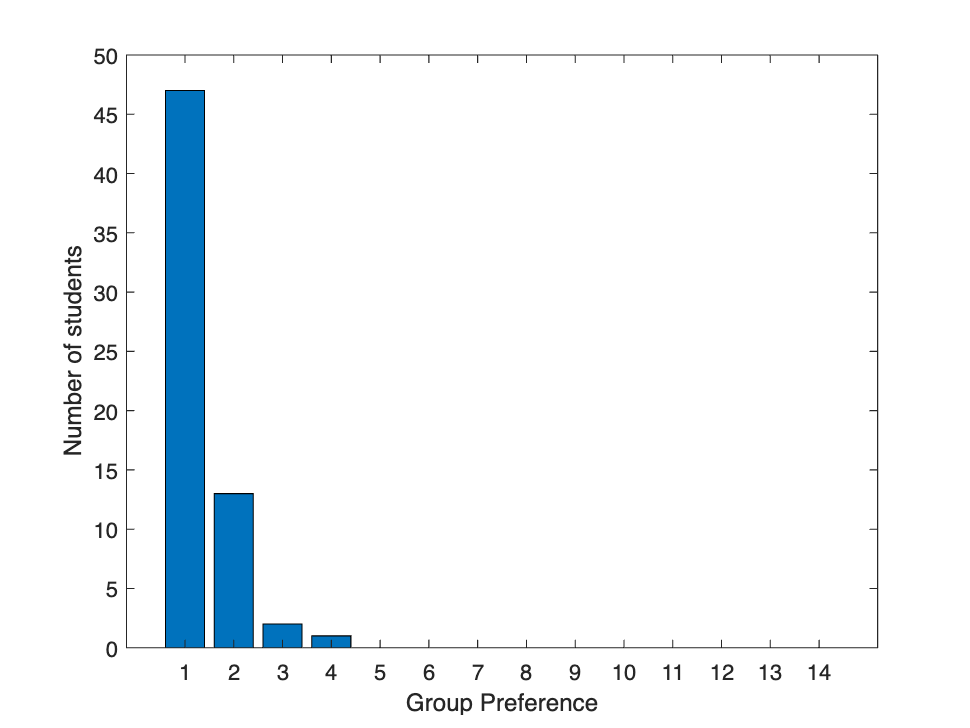

% plot how many of each choice:
choices = [];
for i = 1:14
    choices(i) = sum(og_choiceAllocations(:) == i);
end

bar(choices); 
xlabel("Group Preference");
ylabel("Number of students");

choice1 = choices(1)

choice1 = 47

choice2 = choices(2)

choice2 = 13

choice3 = choices(3)

choice3 = 2

choice4 = choices(4)

choice4 = 1

### d) Set a hard limit on the worst preference allowed:

To implement this the A_eq matrix should be copied (into A_hard) to contain the values of c instead of ones. This will mean that the limits imposed by a copy of b_eq (b_hard) will be used as hard limits on choice maximum, in the form of A_hard*x <=b_hard. This will be appended to the A inequality matrix: (everything else will stay the same.

A_hard = A1;
A_hard_circ = zeros(students,total);
A_hard_circ(1,1:groups) = c(1,:);
for i = 1:students-1
    A_hard_circ(i+1,(groups*i)+1:(groups*(i+1))) = c(i+1,:);
end

A_hard_circ

A_hard_circ =     10     2     5     9     1    14     6     3    12     4    13     7    11     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    11     6     2    10     8     7     4     5     9     1    13     3    14    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     7     9    13    12     3     1    14    11     5    10     2     6     8     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

b_hard will be just the maximum choice allocation

max_choice = 3;
b_hard = max_choice*ones(students,1);

New intlinprog call

[x, fval] = intlinprog(f, intcon, [A;A_hard_circ], [b;b_hard], A_eq, b_eq,lb, ub);

No feasible solution found.

Intlinprog stopped because no point satisfies
the constraints.



There should be no feasible solutions as now with a lower value of r. There is no integer solution that will satisfy a smaller maximum preferrence than 4 as that is already being optimised, and values of r greater than 4 also do not affect the result as that would be not optimal.

### e) Exploration and Experimentation

#### Replacing the cost matrix with higher powers

all_choices = [];
for power = 1: 20
    c_power = c.^power;
    f_power = reshape(c_power',[],1);

    % Run intlinprog
    [x, fval] = intlinprog(f_power, intcon, A, b, A_eq, b_eq,lb, ub);
    
    solutions = reshape(x, groups,students)';
    choiceAllocations = solutions.*c;

    % how many of each choice:
    choices = [];
    for i = 1:14
        choices(i) = sum(choiceAllocations(:) == i);
    end

    all_choices(power,:) = choices;

end

LP:                Optimal objective value is 83.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0
(the default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the default
value).

LP:                Optimal objective value is 133.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0
(the default value). The intcon variables are


all_choices

all_choices =     47    13     2     1     0     0     0     0     0     0     0     0     0     0
    47    13     2     1     0     0     0     0     0     0     0     0     0     0
    45    16     1     1     0     0     0     0     0     0     0     0     0     0
    45    16     1     1     0     0     0     0     0     0     0     0     0     0
    45    16     1     1     0     0     0     0     0     0     0     0     0     0
    45    16     1     1     0     0     0     0     0     0     0     0     0     0
    45    16     1     1     0     0     0     0     0     0     0     0     0     0
    45    16     1     1     0     0     0     0     0     0     0     0     0     0
    45    16     1     1     0     0     0     0     0     0     0     0     0     0
    45    16     1     1     0     0     0     0     0     0     0     0     0     0


Some values have changed but not many, the worst allocation is still a 4th choice group. The power stops making a difference once the cost matrix is cubed. Strangely this means that the number of second choice options increases at the cost of fewer first and third choice. This is perhaps because the 4th choice option has to be used otherwise the solution is very different.

#### How does varying group size impact the solution?

counter = 1;
all_choices = zeros(14*14,14);

for min_group = 1:14   
    for max_group = 1:14
        b2_min = min_group * ones(1,groups);
        b3_max = max_group * ones(1,groups);
        b = [ b3_max'; -b2_min'];
        
        % Run intlinprog
        [x, fval,exitflag, output] = intlinprog(f, intcon, A, b, A_eq, b_eq,lb, ub);
        if(isempty(x))   
        else
            solutions = reshape(x, groups,students)';
            choiceAllocations = solutions.*c;
    
            % how many of each choice:
            choices = [];
            for i = 1:14
                choices(i) = sum(choiceAllocations(:) == i);
            end
            all_choices(counter,:) = choices;
        end
        if(isempty(fval))
            fval = 0;
        end
        fval_table(counter,1) = fval;
        fval_table(counter,2) = min_group;
        fval_table(counter,3) = max_group;
            
        counter= counter + 1;
    end
end

No feasible solution found.

Intlinprog stopped because no point satisfies
the constraints.


No feasible solution found.

Intlinprog stopped because no point satisfies
the constraints.


No feasible solution found.

Intlinprog stopped because no point satisfies
the constraints.


No feasible solution found.

Intlinprog stopped because no point satisfies
the constraints.

LP:                Optimal objective value is 82.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the

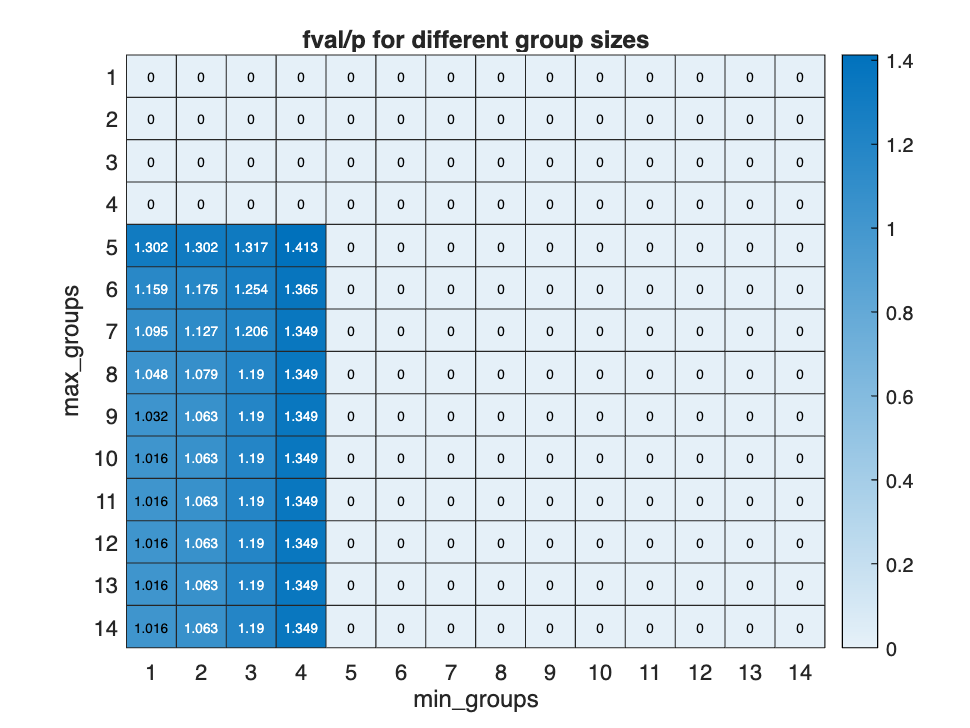

fval_table;
% heatmap of all feasible solutions
fvals = fval_table(:,1)./students;
min_groups = fval_table(:,2);
max_groups = fval_table(:,3);
tbl = table(fvals,min_groups,max_groups);
h = heatmap(tbl,'min_groups','max_groups',ColorVariable='fvals',Title="fval/p for different group sizes"); 

The table above shows how the objective value varies with the group size limitation. As expected the lowest fval occurs when the min number is 1 and the max groups is large. Intlinprog return no solution (seen here as 0) when the minimum group size is greater than 63/14 = 4.5 or when the maximum group size is smaller than 4.5.

#### Randomising row order of cost matrix

% run random perm
random_c = c(randperm(size(c, 1)), :);


f = reshape(random_c',[],1);
% A for max and min group size
A2 = eye(groups);
A2 = repmat(A2, 1, students);
A3 = A2;
% b for max and min group size
minGroup = 3;
maxGroup = 5;
b2_min = minGroup * ones(1,groups);
b3_max = maxGroup * ones(1,groups);
% intcon
intcon = [1:total];
% bounds
lb = zeros(total, 1);
ub = ones(total, 1);
% Arranging for intlinprog
A = [A3;-A2];
b = [ b3_max'; -b2_min'];
A_eq = A1;
b_eq = b1';


% Run intlinprog
[x, fval] = intlinprog(f, intcon, A, b, A_eq, b_eq,lb, ub);

LP:                Optimal objective value is 83.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the
optimal value, options.AbsoluteGapTolerance = 0
(the default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the default
value).



solutions = reshape(x, groups,students)';

% Show results
rand_choiceAllocations = solutions.*random_c;
% worst choice value:
worst_choice_allocated = max(max(rand_choiceAllocations))

worst_choice_allocated = 4

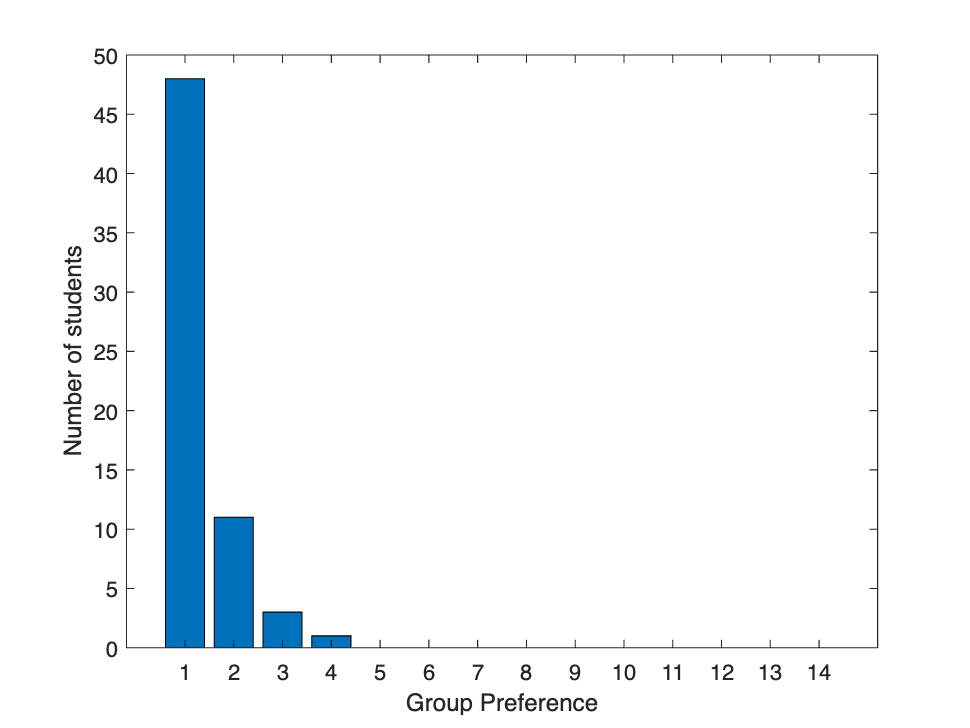


% plot how many of each choice:
choices = [];
for i = 1:14
    choices(i) = sum(rand_choiceAllocations(:) == i);
end

bar(choices); 
xlabel("Group Preference");
ylabel("Number of students");

The random permutation of the rows in the cost matrix does not appear to effect the allocation of groups and the work choice is not impacted.